# Canny Edge Detection

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-20

### Filter Images with Derivatives of Gaussian 

clear; close all; clc

img = imread('PinClipart.com_duck-clip-art-black_522802.png');

imgg = rgb2gray(img);
imgg = imresize(imgg,0.8);
imgg = im2double(imgg);

prewitt_x = [-ones(3,1) zeros(3,1) ones(3,1)];
prewitt_y = - transpose(prewitt_x);

sobel_x = prewitt_x;
sobel_x(2,1)=-2; sobel_x(2,3)=2;
sobel_y = -transpose(sobel_x);

fx= imfilter(imgg,sobel_x);
fy= imfilter(imgg,sobel_y);
fxy = sqrt(fx.^2 + fy.^2);

fig2 = figure(2);
subplot(221); imshow(imgg);
subplot(222); imshow(fx);
subplot(223); imshow(fy);
subplot(224); imshow(fxy);
set(fig2,'Position', [100 100 1500 600]);

figure(3); imshow(fxy)
figure(4); imshow(imcrop(fxy,[660 262 100 100]));


### Non-maximum Suppression (1D)

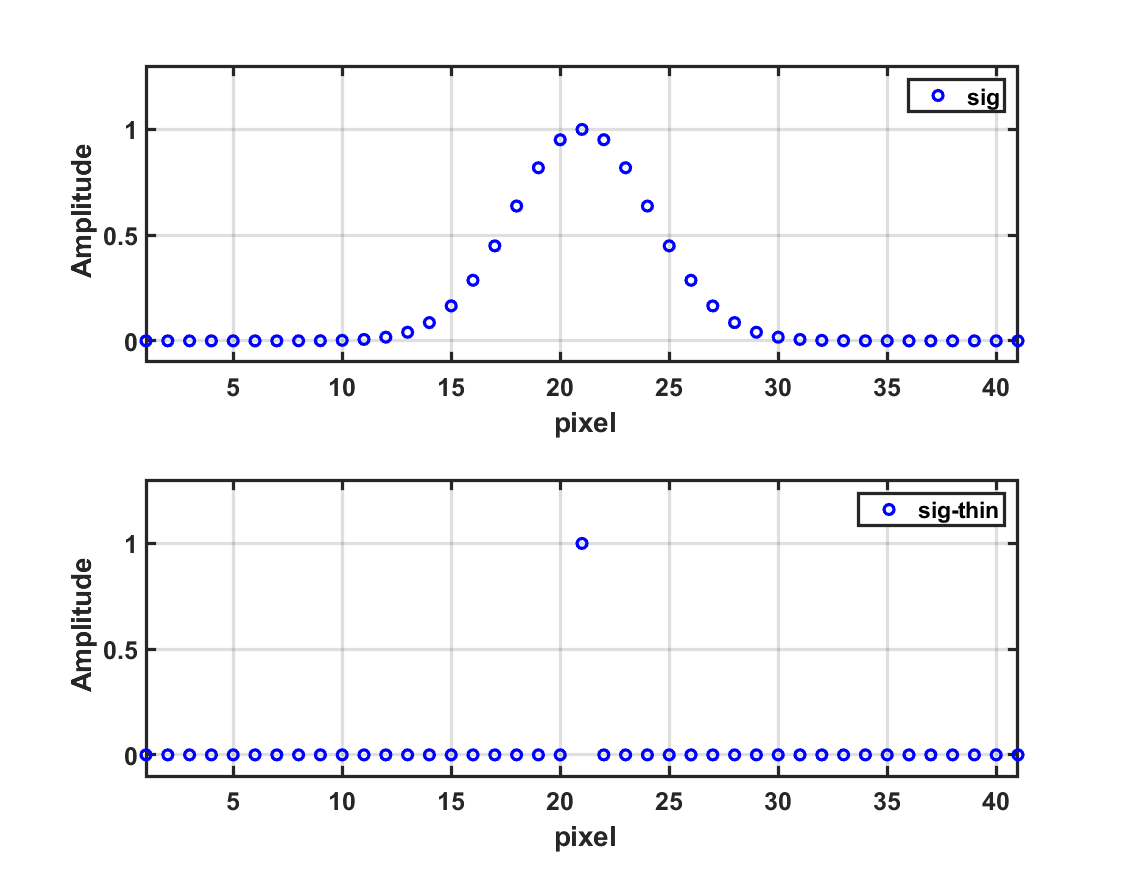

clear; close all; clc;

a = 5;

x = @(t) exp(-a.*t.*t);
x_in = @(t, w) x(t)*exp(-sqrt(-1)*w*t);
Xw = @(w) integral(@(t) x_in(t, w), -inf, inf,'ArrayValued',true);
Xw_analytic = @(w) sqrt(pi/a).*exp(-w.*w/(4*a));

t = -2:0.1:2;
w = [-12:0.1:12] +realmin;

amp = x(t);

amp_thin = zeros(size(amp));
for ii=2:numel(t)-1
    amp_thin(ii) = amp(ii) == max([amp(ii-1), amp(ii), amp(ii+1)]);
end

fig1 = figure(1);
set(fig1,'Position', [100 100 900 700]);

subplot(211); plot(1:numel(t),amp,'ob', 'linewidth', 2); legend('sig');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf pixel'); ylim([-0.1 1.3])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(1:numel(t),amp.*amp_thin,'ob', 'linewidth', 2); legend('sig-thin');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf pixel'); ylim([-0.1 1.3])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Non-maximum Suppression

img = imread('PinClipart.com_duck-clip-art-black_522802.png');

imgg = rgb2gray(img);
imgg = imresize(imgg,0.8);
imgg = im2double(imgg);

prewitt_x = [-ones(3,1) zeros(3,1) ones(3,1)];
prewitt_y = - transpose(prewitt_x);

sobel_x = prewitt_x;
sobel_x(2,1)=-2; sobel_x(2,3)=2;
sobel_y = -transpose(sobel_x);

fx= imfilter(imgg,sobel_x); % x derivatives of Gaussian 
fy= imfilter(imgg,sobel_y); % y derivatives of Gaussian 
fxy = sqrt(fx.^2 + fy.^2);

aimg = atan2(fy, fx); % orientation of gradient

nan_loc = (fx == 0 | fy == 0); % pixels that have no gradient. 

aimg = aimg*180/pi;
aimg(aimg<0) = aimg(aimg<0) + 360; % correct minus orientation

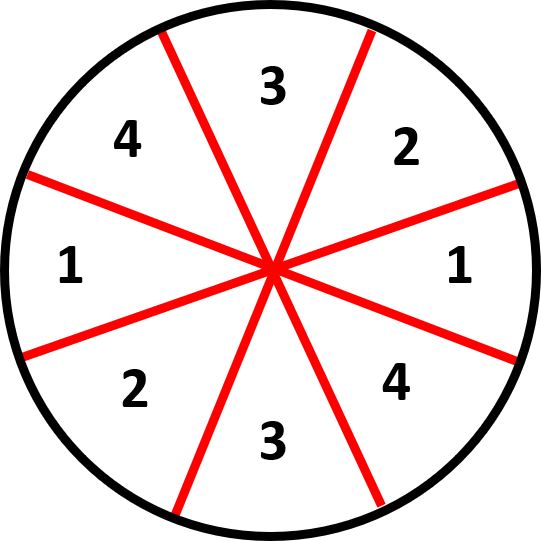

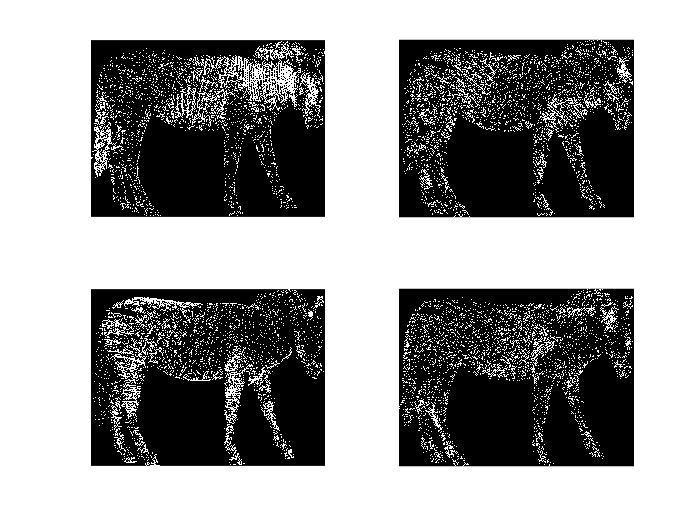

indx = aimg > (360-22.5) | aimg <= (0 + 22.5) | (aimg > (180-22.5) & aimg <= (180+22.5)); % 1
ind1 = (aimg > (45-22.5) & aimg <= (45+22.5)) | (aimg > (225-22.5) & aimg <= (225+22.5)); % 2
indy = (aimg > (90-22.5) & aimg <= (90+22.5)) | (aimg > (270-22.5) & aimg <= (270+22.5)); % 3
ind2 = (aimg > (135-22.5) & aimg<= (135+22.5)) | (aimg > (315-22.5) & aimg<= (315+22.5)); % 4

aimg(indx) = 1;
aimg(ind1) = 2;
aimg(indy) = 3;
aimg(ind2) = 4;
aimg(nan_loc) = 0; % set zero when the pixels have no orientation

figure(1)
subplot(221); imshow(aimg==1);
subplot(222); imshow(aimg==2);
subplot(223); imshow(aimg==3);
subplot(224); imshow(aimg==4);

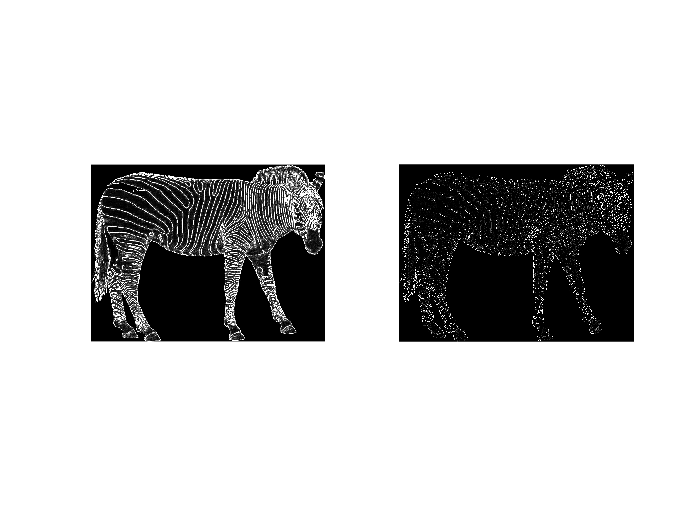



% edge thinning
img_bw = zeros(size(aimg));

for ii=2:size(aimg,1)-1
    for jj=2:size(aimg,2)-1
        
        if aimg(ii,jj) == 1
            img_bw(ii,jj) = fxy(ii,jj) == max([fxy(ii, jj-1), fxy(ii, jj), fxy(ii, jj+1)]);
        elseif aimg(ii,jj) == 2
            img_bw(ii,jj) = fxy(ii,jj) == max([fxy(ii-1, jj+1), fxy(ii, jj), fxy(ii+1, jj-1)]);
        elseif aimg(ii,jj) == 3
            img_bw(ii,jj) = fxy(ii,jj) == max([fxy(ii, jj-1), fxy(ii, jj), fxy(ii, jj+1)]);
        elseif aimg(ii,jj) == 4
            img_bw(ii,jj) = fxy(ii,jj) == max([fxy(ii-1, jj-1), fxy(ii, jj), fxy(ii+1, jj+1)]);
        end
    end
end


figure(2);
subplot(121); imshow(fxy);
subplot(122); imshow(fxy.*img_bw);

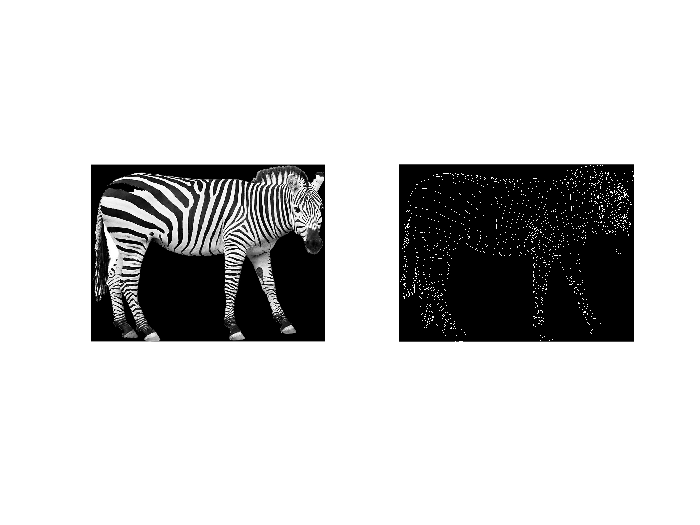



figure(3);
img_canny = edge(imgg, 'Canny', [0.1 0.5]);
subplot(121); imshow(imgg);
subplot(122); imshow(img_canny);

imwrite(img_canny, 'zebra_edge.jpg')

### Effect of Gaussian Kernel Sizes

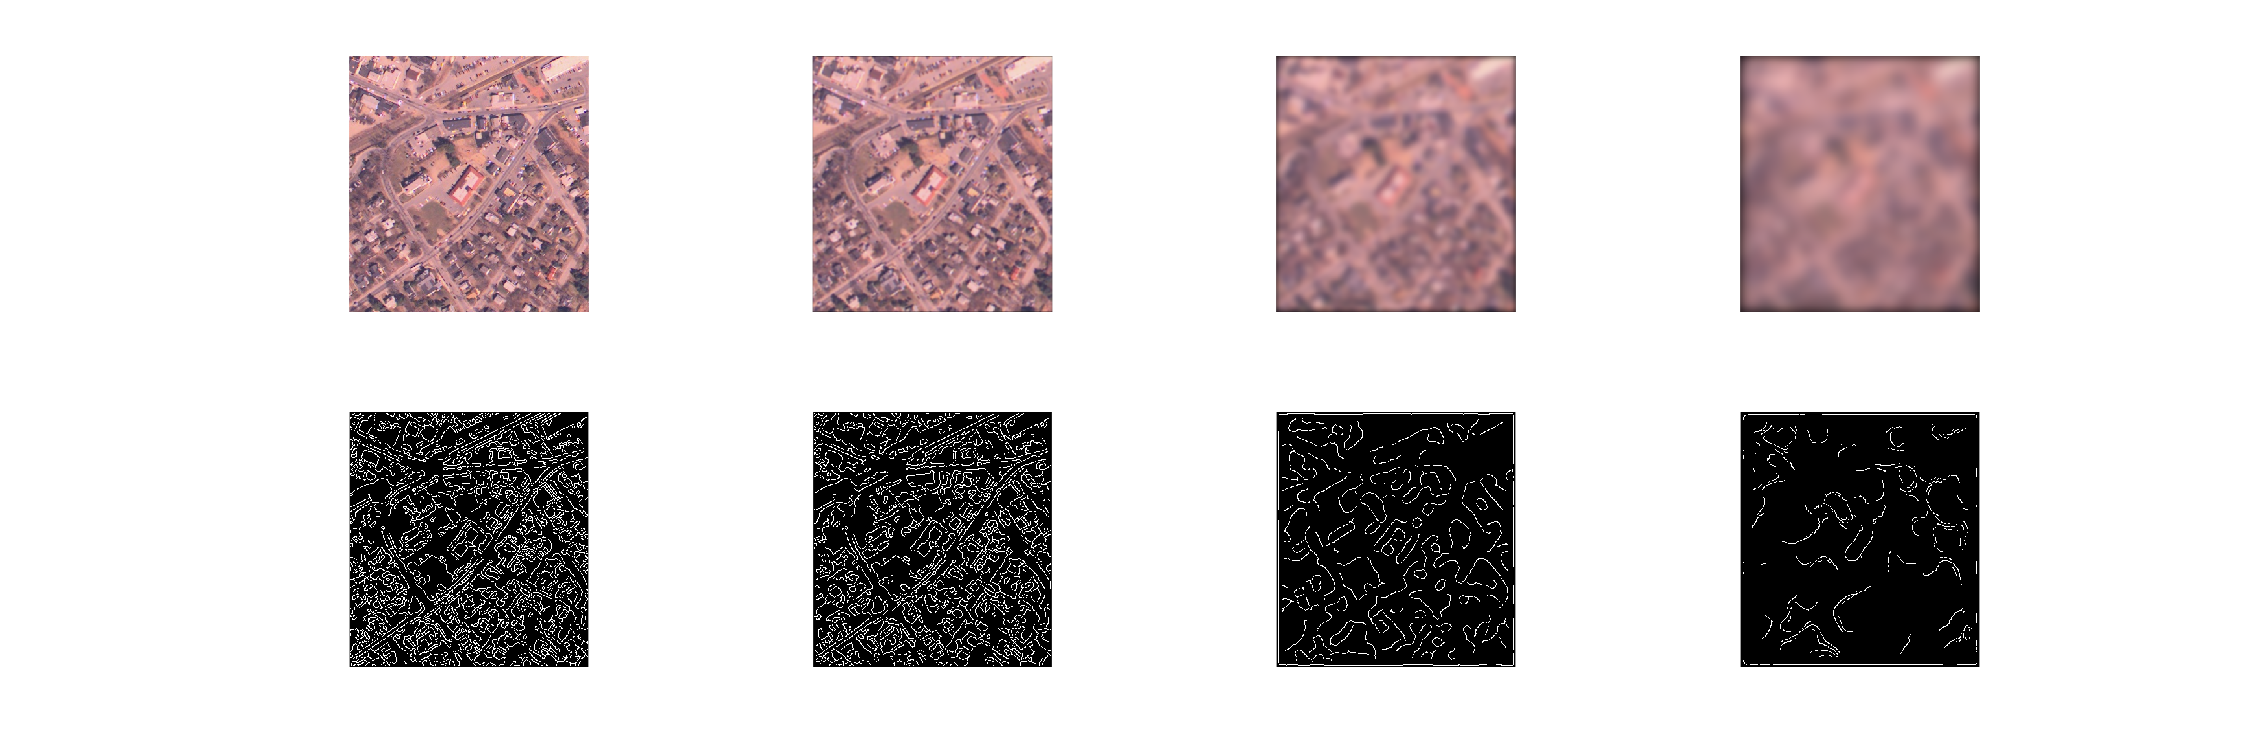

clear; close all; clc;

img = imread('westconcordaerial.png');

f1 =  fspecial('gaussian', 101,1);
f2 =  fspecial('gaussian', 101,5);
f3 =  fspecial('gaussian', 101,10);

img_f1 = imfilter(img, f1);
img_f2 = imfilter(img, f2);
img_f3 = imfilter(img, f3);

fig1 = figure(1);
subplot(241); imshow(img);
subplot(242); imshow(img_f1);
subplot(243); imshow(img_f2);
subplot(244); imshow(img_f3);


BW_filt = edge(rgb2gray(img), 'Canny');
BW_filt_f1 = edge(rgb2gray(img_f1), 'Canny');
BW_filt_f2 = edge(rgb2gray(img_f2), 'Canny');
BW_filt_f3 = edge(rgb2gray(img_f3), 'Canny');

subplot(245); imshow(BW_filt);
subplot(246); imshow(BW_filt_f1);
subplot(247); imshow(BW_filt_f2);
subplot(248); imshow(BW_filt_f3);
set(fig1,'Position', [100 100 1800 600]);

### Effect of High and Low Threshold

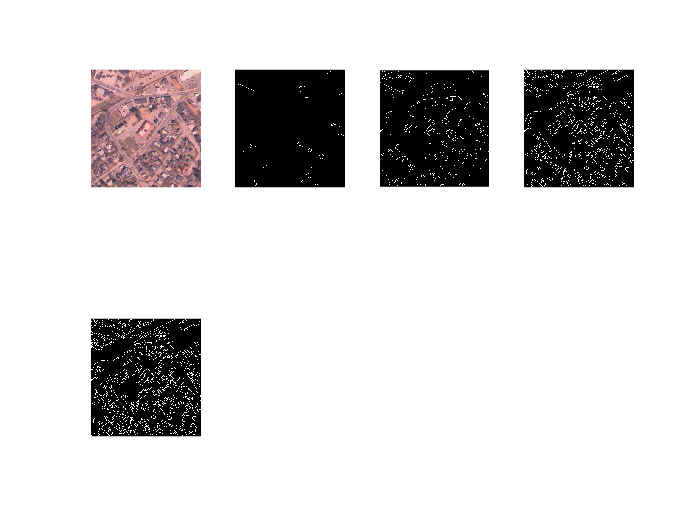

clear; close all; clc;

img = imread('westconcordaerial.png');

f = fspecial('gaussian', 3);
img_f = imfilter(img, f);

fig1 = figure(1);
subplot(241); imshow(img_f);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.4 0.8]);
subplot(242); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.4 0.5]);
subplot(243); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.2 0.5]);
subplot(244); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.1 0.5]);
subplot(245); imshow(BW_filt);

### Beam

clear; close all; clc;

img = imread('beam.jpg');

f = fspecial('gaussian', 6,1);
img_f1 = imfilter(img, f);
BW_filt1 = edge(rgb2gray(img_f1), 'Canny');

f = fspecial('gaussian', 13,2);
img_f2 = imfilter(img, f);
BW_filt2 = edge(rgb2gray(img_f2), 'Canny');

f = fspecial('gaussian', 19,3);
img_f3 = imfilter(img, f);
BW_filt3 = edge(rgb2gray(img_f3), 'Canny');

f = fspecial('gaussian', 25,4);
img_f4 = imfilter(img, f);
BW_filt4 = edge(rgb2gray(img_f4), 'Canny');

figure(1);
subplot(221); imshow(BW_filt1)
subplot(222); imshow(BW_filt2)
subplot(223); imshow(BW_filt3)
subplot(224); imshow(BW_filt4)
